## Harmonic motion

Showing the effect of phase changes on a sine wave

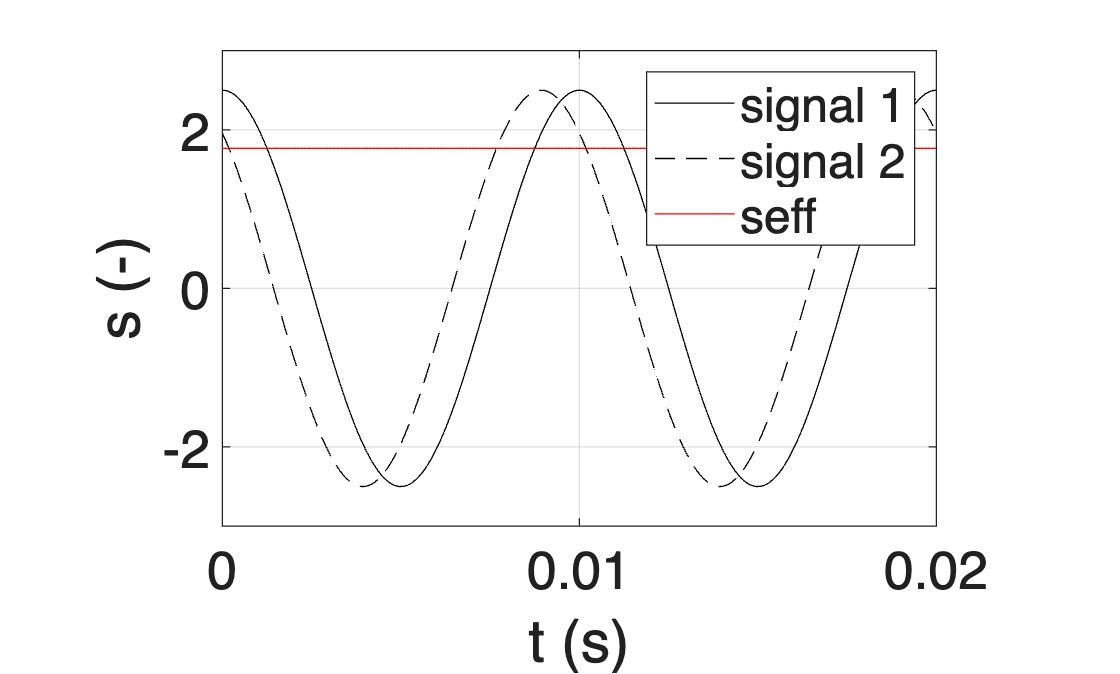

f       =   100;                           %   frequency (Hz)
s_amp   =   2.6;           %   amplitude of waves (-)
time    =   2;                              %   time duration of signals (s)
phi     =0.51;      %   phase of signal 2 (rad)

sine_waves(f,s_amp,phi,time);

## Complex function

Displaying the amplitude, real and imaginary part of a complex function

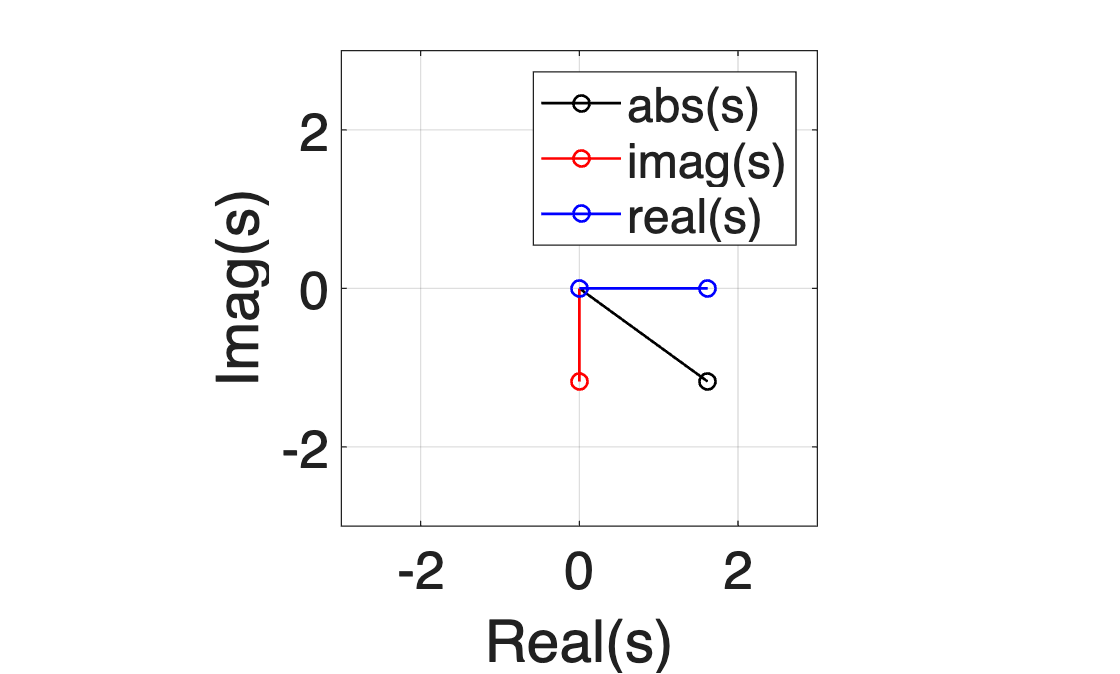

f = 100;                        % frequency (Hz), keep it fixed
s_amp = 2;                      % amplitude
t = 0.0008;       % time in s

complex_numbers(f,s_amp,t)

## Transient response

Transient harmonic signal

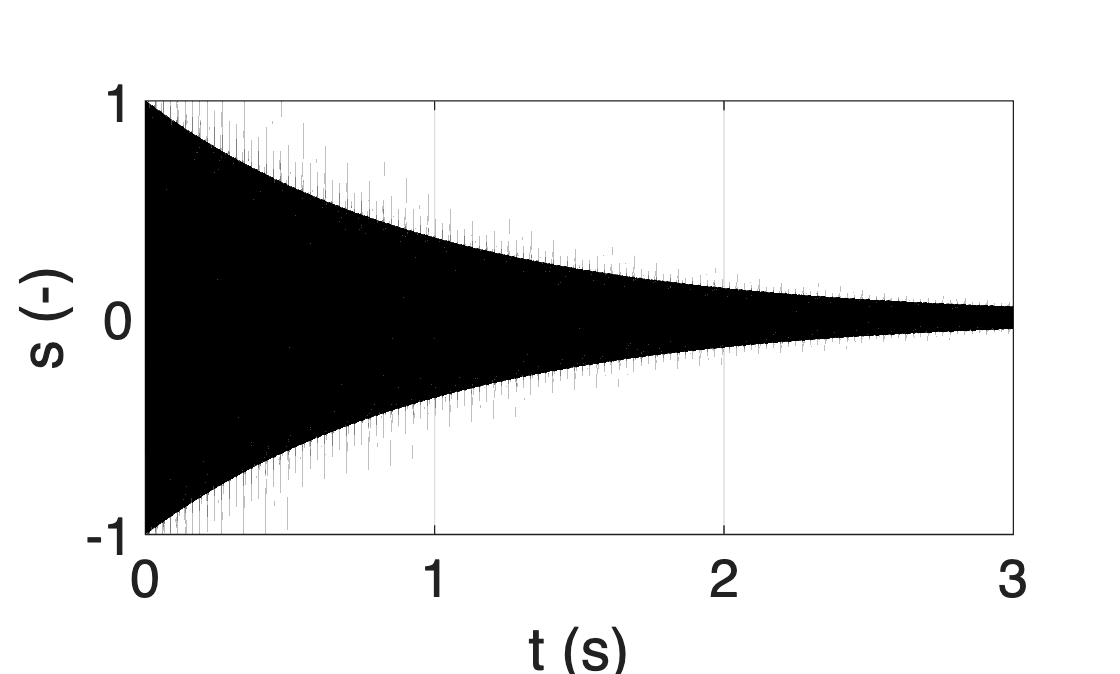

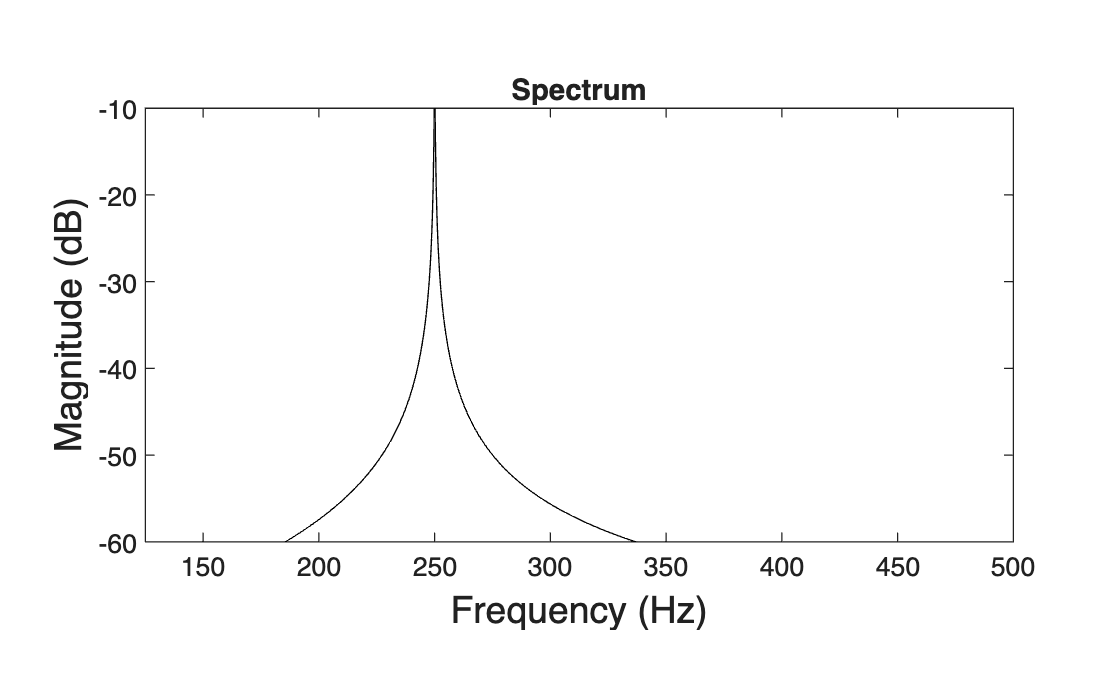

f = 250;
fs = 48000;
delta = 1;
T = 3;
close all

s=transient_response(f,delta,T,fs);

soundsc(s,fs)


### Period signals

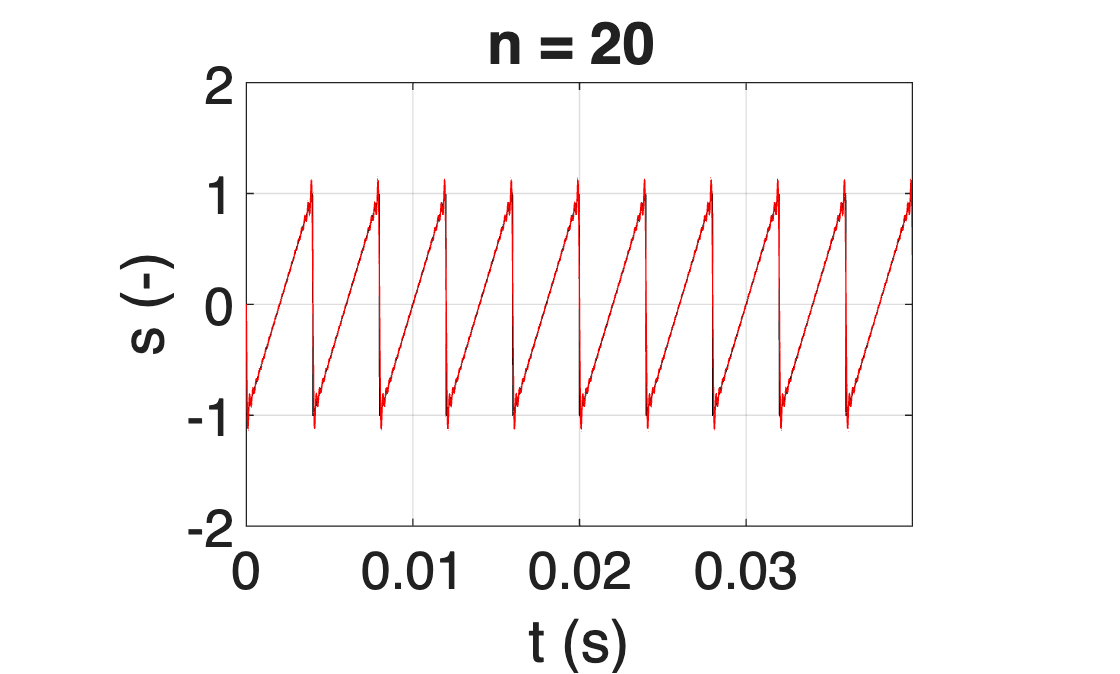

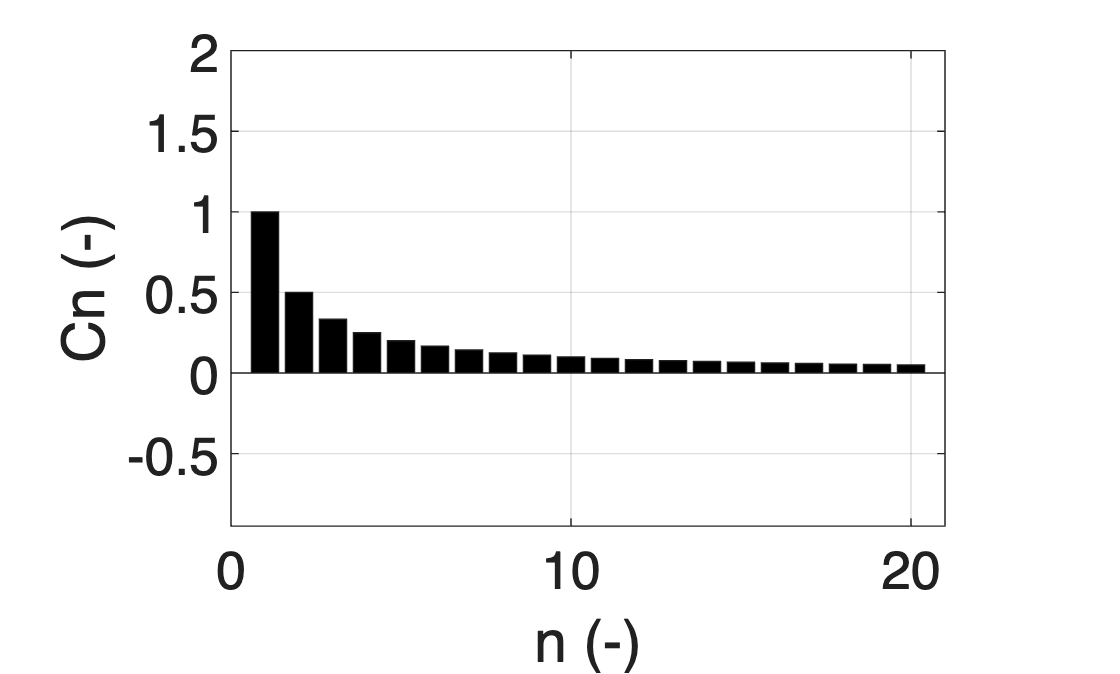

f = 250;
s_amp = 1;
fs = 48000;
nmax = 20;

periodicsignal(f,s_amp,fs,nmax)

### Time and frequency signals

Time signals and their frequency domain counterpart

Start speaking.
End of Recording.


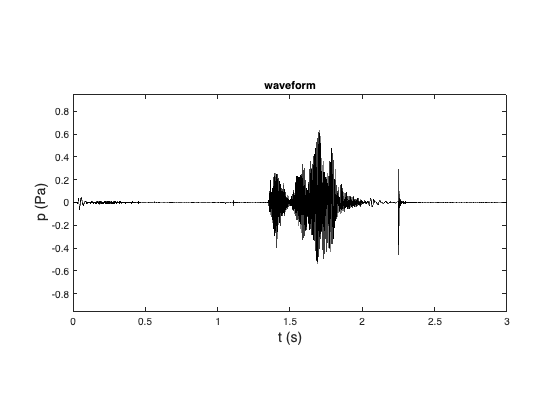

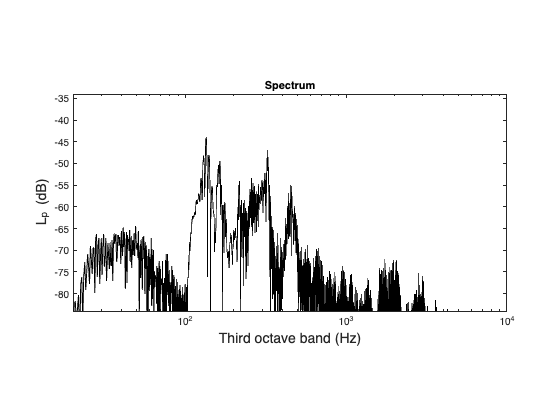

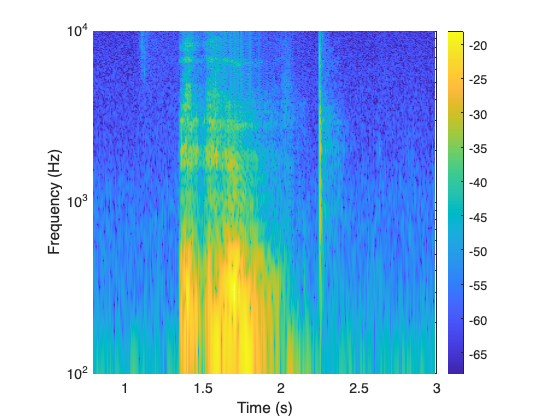

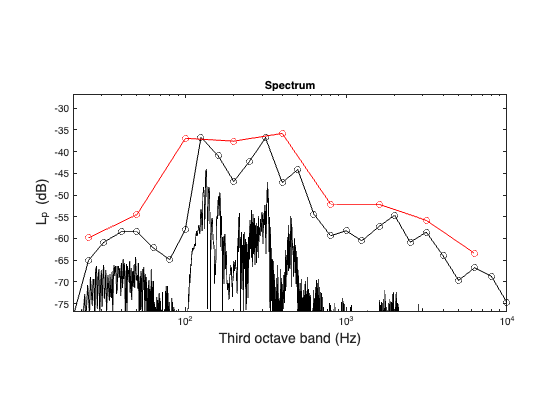

fs = 44100;         % sample frequency (Hz)
slength = 3;        % length of signal in seconds

audiorecordingEAA(fs,slength)

### Help functions

Feel free to modify to make it better!

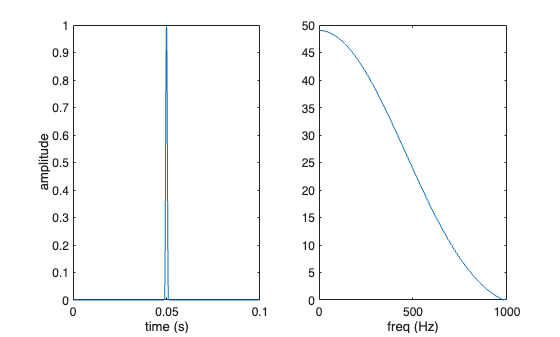

fs = 48000;     % sample rate (in Hz)
t = 0.1;        % time (in s)
width = 98; % width of impulse (in samples)
impulse_width(fs, t, width);

function sine_waves(f,s_amp,phi,time)
close all

omega = 2*pi*f;
T = time./f;
dt = 1./48000;
t = [0:dt:T];
s = s_amp.*cos(omega.*t+phi);
s2 = s_amp.*cos(omega.*t);

% Harmonic motion

figure(1);
plot(t,s2,'k',t,s,'k--',t,s_amp./sqrt(2).*ones(length(t),1),'r')
xlabel(['t (s)'],'FontSize',20)
ylabel(['s (-)'],'FontSize',20)
set(gca,'FontSize',20)
grid on
axis([t(1) t(end) -3 3])
legend('signal 1','signal 2','seff')
set(gca,'FontSize',20,'PlotBoxAspectRatio',[1.5 1 1])
box on

end


% Complex representation

function complex_numbers(f,s_amp,t)
omega = 2*pi*f;
phi = 0;

% animation complex numbers
s = s_amp.*exp(j.*(omega.*t+phi));
close all
figure(20)
plot([0 real(s)],[0 imag(s)],'ko-','LineWidth',1)
hold on;plot([0 0],[0 imag(s)],'ro-','LineWidth',1)
hold on;plot([0 real(s)],[0 0],'bo-','LineWidth',1)
axis([-1.5 1.5 -1.5 1.5].*s_amp)
legend('abs(s)','imag(s)','real(s)')
grid on
set(gca,'FontSize',20,'PlotBoxAspectRatio',[1 1 1])
xlabel('Real(s)')
ylabel('Imag(s)')

end

% Transient response

function s=transient_response(f,delta,T,fs)
omega0 = 2*pi*f;
dt = 1./fs;
t = [0:dt:T-dt];
v0 = 1;

s = v0.*exp(-delta.*t).*cos(omega0.*t);
figure(23)
plot(t,s,'k')
axis([0 T -v0 v0])
xlabel(['t (s)'],'FontSize',20)
ylabel(['s (-)'],'FontSize',20)
set(gca,'FontSize',20,'PlotBoxAspectRatio',[2 1 1])
grid on

Y = fft(s).*dt;
Lp= 20.*log10(abs(Y));%./max(abs(Y)));
%max(Lp)
fv = [0:fs*T-1]./T;
figure(24)
plot(fv,Lp,'k');
set(gca,'FontSize',10,'PlotBoxAspectRatio',[2 1 1])
axis([f/2 f*2 -60 -10])
xlabel('Frequency (Hz)','FontSize',14)
ylabel('Magnitude (dB)','FontSize',14)
title('Spectrum')
box on

end

% Period signals
function periodicsignal(f,s_amp,fs,nmax)

T = 1./f;
dt = 1./fs;
t = [-T/2:dt:T/2-dt];

s = 2*s_amp.*t./T;
stot= repmat(s,1,10);
ttot = [0:dt:10.*T-dt];
C = zeros(1,length(s));
%soundsc(repmat(stot,1,10),fs)

for n = 1:nmax
    Cn(n) = 1/n;
    if mod(n,2) == 0
        C = C-2.*s_amp./pi.*sin(n.*2.*pi*t./T).*Cn(n);
    else
        C = C+2.*s_amp./pi.*sin(n.*2.*pi*t./T).*Cn(n);
    end
    Ctot= repmat(C,1,10);
end

figure(25)
plot(ttot,stot,'k',ttot,Ctot,'r')
axis([0 max(ttot) -2*s_amp 2*s_amp])
xlabel(['t (s)'],'FontSize',20)
ylabel(['s (-)'],'FontSize',20)
set(gca,'FontSize',20,'PlotBoxAspectRatio',[1.5 1 1])
title(['n = ',num2str(n),' '])
grid on

pause(1)
soundsc(repmat(Ctot,1,10),fs)

figure(26)
bar(1:nmax,Cn,'k')
axis([0 nmax+1 min(Cn)-1 max(Cn)+1])
xlabel(['n (-)'],'FontSize',20)
ylabel(['Cn (-)'],'FontSize',20)
set(gca,'FontSize',20,'PlotBoxAspectRatio',[1.5 1 1])
grid on

end


function audiorecordingEAA(fs,slength)
close all
bits = 16;
recObj = audiorecorder(fs, bits, 1);

% Collect a sample of your speech with a microphone, and plot the signal data:
disp('Start speaking.')
recordblocking(recObj, slength);
disp('End of Recording.');

% Store data in double-precision array.
myRecording = getaudiodata(recObj);
y=myRecording;

dt = 1./fs;
Y = fft(y).*dt;
Lp= 20.*log10(abs(Y)./slength);
f = [0:fs*slength-1]./slength;
df = 1./slength;
fcenter=[20 25 31 40 50 63 80 100 125 160 200 250 315 400 500 630 800 1000 1250 1600 2000 2500 3150 4000 5000 6300 8000 10000 12500 16000 20000];
fcenterfull = fcenter(2:3:end);
% 1/3 octave bands
flower=round(2^(-1/6).*fcenter);
flowerfull=round(2^(-1/2).*fcenterfull);

for ff=1:length(flower)-1;
    f1 = flower(ff);
    f2 = flower(ff+1);

    aa = find(f >= f1);
    bb = find(f < f2);
    fthird = aa(1):1:bb(end);

    % Lp per 1/3 octave band
    Lp_third(ff) = 10.*log10(df.*sum(10.^(Lp(fthird)./10)));
    clear aa bb
end
for ff=1:length(flowerfull)-1;
    f1 = flowerfull(ff);
    f2 = flowerfull(ff+1);

    aa = find(f >= f1);
    bb = find(f < f2);
    ffull = aa(1):1:bb(end);

    % Lp per 1/3 octave band
    Lp_full(ff) = 10.*log10(df.*sum(10.^(Lp(ffull)./10)));
    clear aa bb
end

% plot the waveform
figure(30)
plot([1:fs*slength]./fs,y,'k-');
set(gca,'FontSize',10,'PlotBoxAspectRatio',[2 1 1],'Ylim',[-0.1 .1])
axis([0 slength -max(y).*1.5 max(y).*1.5])
xlabel('t (s)','FontSize',14)
ylabel('p (Pa)','FontSize',14)
title('waveform')
box on

% plot the spectrum
figure(31)
semilogx([0:fs*slength-1]./slength,Lp,'k');
set(gca,'FontSize',10,'PlotBoxAspectRatio',[2 1 1],'Ylim',[-20 0],'Xlim',[20 1e4])
axis([20 1e4 max(Lp)-40 max(Lp)+10])
xlabel('Third octave band (Hz)','FontSize',14)
ylabel('L_p (dB)','FontSize',14)
title('Spectrum')
box on

% plot the spectrogram
[S,F,T,P2] = spectrogram(y,fs/100,100,logspace(2,4,512*2),fs);

figure(32)
surf(T,F,10*log10((sqrt(abs(P2)))),'edgecolor','none'); axis tight;
view(0,90);
xlabel('Time (s)'); ylabel('Frequency (Hz)');
P2max =max (10*log10((sqrt(abs(P2(:))))));
caxis([P2max-50 P2max])
colorbar
shading interp

axis([0.8 slength 100 1e4])
set(gca,'YScale','log','FontSize',14,'PlotBoxAspectRatio',[1 1 1])
box on
%Lp-20.*log10(slength),
% plot the spectrum
figure(43)
semilogx([0:fs*slength-1]./slength,Lp,'k');
hold on;plot(fcenter(1:end-1),Lp_third,'ko-');
hold on;plot(fcenterfull(1:end-1),Lp_full,'ro-');
set(gca,'FontSize',10,'PlotBoxAspectRatio',[2 1 1],'Ylim',[-20 0],'Xlim',[20 1e4])
axis([20 1e4 max(Lp_third)-40 max(Lp_third)+10])
xlabel('Third octave band (Hz)','FontSize',14)
ylabel('L_p (dB)','FontSize',14)
title('Spectrum')
box on
end

function impulse_width(fs, t, width)

sampleIdx = 1:t*fs;
x = ((sampleIdx(end/2)-width/2):(sampleIdx(end/2)+width/2)) / fs;
y = zeros(t * fs, 1);
y(round(x*fs)) = hann(length(x));
fftData = abs(fft(y, fs));

subplot(121)
plot((1:t*fs)/fs, y)
xlabel("time (s)")
ylabel("amplitude")
subplot(122)
plot(fftData(1:1000));
xlabel("freq (Hz)")

end
